% generate figure 3
% dependence: initRSG2prior, v2struct

### set up

S=initRSG2prior;
v2struct(S); % behDir

### main loop

disp('==========');

disp('fig3AB');

fig3AB


===== H_RSGprior_20161210 =====
outlier trials (incl. abort/wait): 674/1546,43.5964%
outlier trials (w/o abort/wait): 48/1546,3.1048%
cluster#3011: #sp=24677


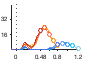

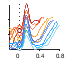

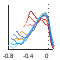

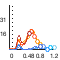

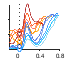

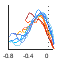

===== H_RSGprior_20161214 =====
outlier trials (incl. abort/wait): 464/1761,26.3487%
outlier trials (w/o abort/wait): 52/1761,2.9529%
cluster#2159: #sp=101345


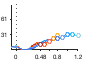

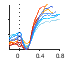

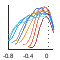

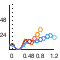

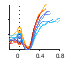

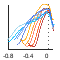

===== H_RSGprior_20161218 =====
outlier trials (incl. abort/wait): 487/2097,23.2237%
outlier trials (w/o abort/wait): 56/2097,2.6705%
cluster#2022: #sp=38722


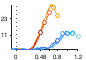

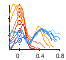

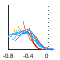

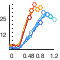

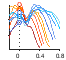

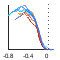

===== G_RSGprior_20170506 =====
outlier trials (incl. abort/wait): 752/2085,36.0671%
outlier trials (w/o abort/wait): 160/2085,7.6739%
cluster#1111: #sp=7444


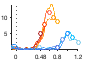

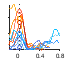

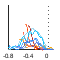

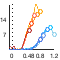

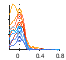

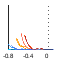

cluster#2096: #sp=19902


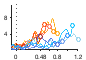

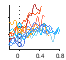

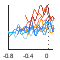

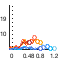

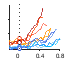

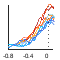

===== G_RSGprior_20170823 =====
outlier trials (incl. abort/wait): 1134/4126,27.4842%
outlier trials (w/o abort/wait): 419/4126,10.1551%
cluster#2111: #sp=95315


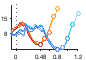

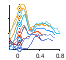

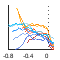

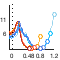

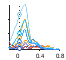

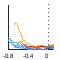

plot_PSTH(S); % fig3AB; fig3C was manually generated from fig3AB


disp('==========');

disp('fig3D');

fig3D


H
# neurons: 533
G
# neurons: 639


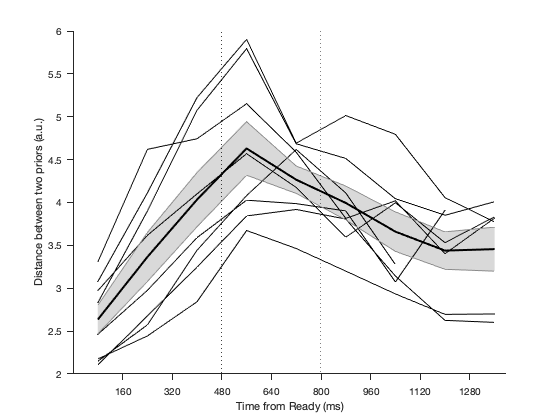

plot_RMS(S); % fig3D


disp('==========');

disp('fig3E');

fig3E


H # neurons: 536
G # neurons: 636
% ts-modulation(short): 23.2082
% ts-modulation(long): 15.8703
% prior-modulation: 62.9693
H


chi2 = 21.8741

pval = 2.9114e-06

   161   228
    29   118

   30.0373   42.5373
    5.4104   22.0149



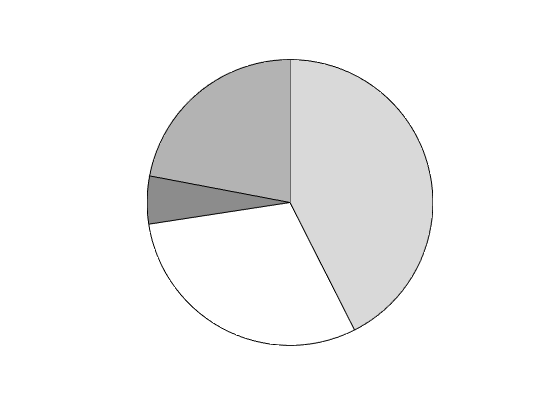

G


chi2 = 4.7142

pval = 0.0299

   180   257
    64   135

   28.3019   40.4088
   10.0629   21.2264



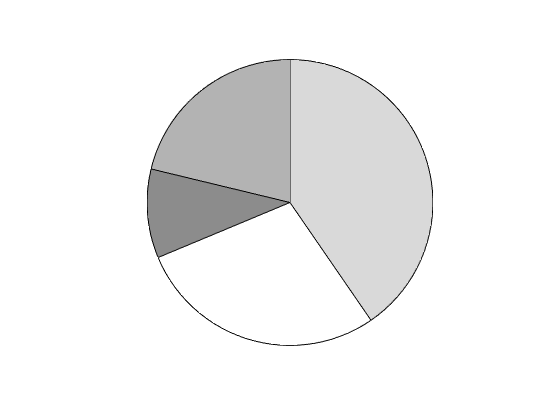

plot_pie(S); % fig3E


disp('==========');

disp('fig3F');

fig3F


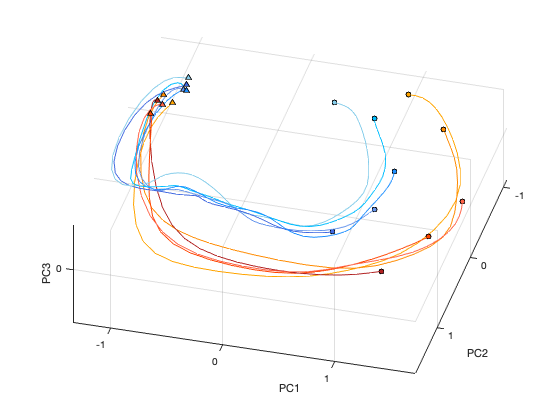

plot_traj_ts(S); % fig3F


disp('==========');

disp('fig3G');

fig3G


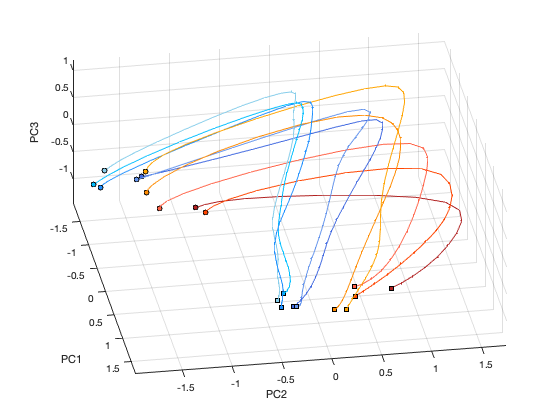

plot_traj_tp(S); % fig3G

function plot_pie(S) % fig3E

v2struct(S);
load('regFinal.mat'); % to find ts-mod cells

disp(['H # neurons: ' num2str(nnz(c(:,1)<170000))]);
disp(['G # neurons: ' num2str(nnz(c(:,1)>170000))]);

% determine neurons modulated by tp: model comparison
modelN={'full_prior','reduced_prior','full_tsShort','reduced_tsShort','full_tsLong','reduced_tsLong'};
nModel=length(modelN); % 7; % [full noTs noTp noPrior wInteract noEH noTarg]
% bic difference: bic = -2*logL + numParam*log(numObs) > % cell(ts modulated)
dBICpr=d(:,1)-d(:,2)+(nP(:,1).*log(nT(:,1))-nP(:,2).*log(nT(:,2))); % -2*LLR(full/ts-reduced)
dBICtsS=d(:,3)-d(:,4)+(nP(:,3).*log(nT(:,3))-nP(:,4).*log(nT(:,4))); % -2*LLR(full/ts-reduced)
dBICtsL=d(:,5)-d(:,6)+(nP(:,5).*log(nT(:,5))-nP(:,6).*log(nT(:,6))); % -2*LLR(full/ts-reduced)
% dBICtp=d(:,1)-d(:,3)+(nP(:,1).*log(nT)-nP(:,3).*log(nT)); % -2*LLR(full/tp-reduced)
% dBIC=bsxfun(@minus,d(:,1),d(:,2:end))+... % repmat(d(:,1),1,nModel-1)-d(:,2:end)+...
%     bsxfun(@minus,nP(:,1).*log(nT),bsxfun(@times,nP(:,2:end),log(nT))); %     (repmat(nP(:,1),1,nModel-1).*log(nT)-nP(:,2:end).*log(nT)); % -2*LLR(full/tp-reduced)
idTsShortMod=dBICtsS<0; disp(['% ts-modulation(short): ' num2str(mean(idTsShortMod)*100)]); % % ts-modulation: 39.7611
idTsLongMod=dBICtsL<0; disp(['% ts-modulation(long): ' num2str(mean(idTsLongMod)*100)]); % % ts-modulation: 39.7611
idPrMod=dBICpr<0; disp(['% prior-modulation: ' num2str(mean(idPrMod)*100)]); % % prior-modulation: 68.3447


for i=1:nAnimal
    disp('=========');
    disp(animalNm{i});
    disp('=========');
    
    % report # cells & %
    tmp=[nnz(~idTsShortMod&~idTsLongMod&idPrMod&idA==i);... % P
        nnz(idTsShortMod&~idTsLongMod&~idPrMod&idA==i);... % TS
        nnz(~idTsShortMod&idTsLongMod&~idPrMod&idA==i);... % TL
        nnz(idTsShortMod&~idTsLongMod&idPrMod&idA==i);... % P*TS
        nnz(~idTsShortMod&idTsLongMod&idPrMod&idA==i);... % P*TL
        nnz(idTsShortMod&idTsLongMod&~idPrMod&idA==i);... % TS*TL
        nnz(idTsShortMod&idTsLongMod&idPrMod&idA==i);... % P*TS*TL
        ];
    
    %% interaction b/t (ts-short|ts-long) & prior
    idTsMod=idTsShortMod | idTsLongMod;
    nMatAn{i}=[nnz(~idTsMod&~idPrMod&idA==i) nnz(~idTsMod&idPrMod&idA==i);... % 2nd col: prior-dep
        nnz(idTsMod&~idPrMod&idA==i) nnz(idTsMod&idPrMod&idA==i)];     % 2nd row: ts-dep
    [chi2,pval]=chi2testIndep(nMatAn{i})
    
    disp(nMatAn{i}); % # cells
    disp(nMatAn{i}./nnz(idA==i)*100); % percent
    
    % reshape so that both-dependent in the middle; both>ts-only>N/A>prior-only
    tmp=[nMatAn{i}(2,2);nMatAn{i}(2,1);nMatAn{i}(1,1);nMatAn{i}(1,2)];
    
    figure(i+1000); setFigPos(1,i);
    p=pie(tmp);
    
    % color & text setting
    for j=2:2:length(tmp)*2
        p(j).String=''; % [num2str(tmp(round((j-1)/2))) '(' num2str(tmp(round((j-1)/2))/sum(tmp)*100,2) '%)']; % '';
    end
    p(1).FaceColor=[.7 .7 .7];
    p(3).FaceColor=[.55 .55 .55];
    p(5).FaceColor=[1 1 1];
    p(7).FaceColor=[.85 .85 .85];
    %
    %
    % %      explode
    %
end

drawnow;
pause(0.5);

end

function plot_traj_ts(S) % fig3F

S.fname='trajKS_ts_EL_H_avgAttB4PCA.mat'; % trajKS_periSet_E2_H_bin20_smth40.mat';
plot_traj(S)

end

function plot_traj_tp(S) % fig3G

S.fname='trajKS_tp_EL_H_bin20_smth40.mat'; % 'trajKS_tp_EL_H.mat'; % trajKS_periSet_E2_H_bin20_smth40.mat';
plot_traj(S)

end


function plot_traj(S)
v2struct(S);
load(fname);

%% initial
idExpFig=0; % 1; % 0; % 1;
idKilosort=0; % 1;

if strfind(fname,'periSet') % trajKS_periSet_ER_H
    idProd=1; % 0; % 1;
    idMeas=1; % 0;
    idAtt=0; % 1; % 1; % 0;
elseif strfind(fname,'ts')
    idProd=0; % 1; % plotting together
    idMeas=1; % 0; % 1;
    idAtt= 0; % 1;
elseif strfind(fname,'tp')
    idProd=1; % plotting together
    idMeas=0; % 1;
    idAtt=0;
else
    idProd=1; % 1; % plotting together
    idMeas=0; % 0; % 1;
    idAtt= 0; % 1;
end

if idKilosort
    fnmEnd='_Kilosort';
else
    fnmEnd=[];
end
idFlipPC3=0; % 1;
idCondSpecific=true; % false;
conditionSpecificPCANm={'condSpecPCA'};
load pplot.mat; % tmpCmap

% figure's PaperUnits: 'inches'
optsExpFig.Height=4.2/2.54; % 2*1.2; % 0.8; % '1.2'; % '2'; % 7;
optsExpFig.Width=4.2/2.54; % 3.6; % 1.5*1.2*2; % '2.4'; % '4';
optsExpFig.FontSize='6';
optsExpFig.FontMode='fixed';
optsExpFig.Format='eps'; % 'tiff'; % 'pdf'; % 'png';
optsExpFig.LockAxes=1;
optsExpFig.LineMode='fixed'; % 'scaled';
%     optsExpFig.LineWidthMin=0.5;
%     optsExpFig.LineWidthMax=1.5;
optsExpFig.LineWidth=.5; %1;
optsExpFig.Renderer='painters';
lw=1; % 1.5;
lw2=1;
msize=5; % 10; % 4;
msize2=1;

nPr=2;    prNm={'Short','Long'};
nEH=2;ehNm={'Eye','Hand'};
nTarg=2; targNm={'Right','Left'}; % [0 180]
nTs=5;
nSplit=2; splitNm={'bias+','bias-'}; % more/less biased; for ts@prior mean, early/late


epNm={'fixation';'targetOn';'periReady';'periSet';'production';'ts';'tp';'_priorS_';'_priorL_';'_priorSL_';'t_s';'t_p';'prior'};
epNm2={'preFix','postFix';'preTOn','postTOn';'preReady','postReady';'','';'prod','postProd';'','';'','';'','';'','';'','';'','';'','';'',''};
for i=1:length(epNm)
    if ~isempty(strfind(fname,epNm{i})), break; end;
end
idEp=i;

animalNm={'H','G'}; % ,'t_s','t_p'};
for i=1:length(animalNm)
    if ~isempty(strfind(fname,['_' animalNm{i} '_'])), break; end;
end
idAnimal=i;

condNm={'ER','EL';'HR','HL';'E2','H2'};
for iEH=1:size(condNm,1)
    for iTh=1:nTarg
        if ~isempty(strfind(fname,condNm{iEH,iTh})),
            idCondSpecific=true; tmpId=[iEH; iTh];
            break;
        end;
    end
end
if ~exist('tmpId','var') % for RNN
    iEH=1;iTh=1;tmpId=[iEH; iTh];
end
% individual sessions' data
if ~isempty(strfind(fname,'_prior_')) % & ~isempty(strfind(fname,'avgDir'))
    tmpCmap{end+1,1}=[0 0 1;0 0 1;0 0 1;0 0 1;0 0 1]; % tmpCmap{1,1};
    linestyle={'-','-','--'};
else
    linestyle={'-','-'};
end % if ~isempty(strfind(fname,'prior')) & ~isempty(strfind(fname,'avgDir'))
% no set

if ~isempty(strfind(fname,'noSet'))
    idNoSet=1;
    linestyle{end+1}='-';
else
    idNoSet=0;
end

%% main
condId=1; % eyeRight
for iEH=1:nEH
    for iTh=1:nTarg
        if idCondSpecific
            tmpD=D;iEH=tmpId(1);iTh=tmpId(2);
            if iEH>2, iEH=2; end; % E2, H2 avgDir
        else
            tmpD=D(condId:4:length(D));
        end
        
        tmpMin=[]; % for setting measure/produce in the same range
        tmpMax=[];
        
        diffV=[];
        sSet=[]; % for curvature
        sSetAll=[]; % all data (binSize20) except before 1st set
        
        if idMeas
            hFig=figure;set(gcf,'position',pplot.(['rect' num2str(iEH) '_' num2str(2*(iTh-1)+1)]));hold all;
            
            % H
            if idAnimal==1
                if strfind(fname,'periSet')
                    set(gca,'View',[29 60]); % [49 24]);
                    grid on; % off;
                else % ts/tp
                    if strfind(fname,'_prior_')
                        if strfind(fname,'supportOnly')
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-24    12]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[-18.0000  -42.4000]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[   51.0000  -44.4000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[ -80.8000   37.2000]); %30 -70]);
                            end
                        else
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-41 -54]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[-110    67.6]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[47 36]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[34 -39]); %30 -70]);
                            end
                        end
                    elseif strfind(fname,'_ts_')
                        if strfind(fname,'depth') %%%%%%
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-17.2000   79.2000]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[-15 -64]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[39.0000  -75.6000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[37.2000  -89.2000]); %30 -70]);
                            end
                        else
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-17.2000   79.2000]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[-15 -64]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[39.0000  -75.6000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[37.2000  -89.2000]); %30 -70]);
                            end
                        end
                    end
                end
                
            else % G
                if strfind(fname,'periSet')
                    set(gca,'View',[57 4]);
                    grid on; % off;
                else
                    if strfind(fname,'_prior_')
                        if strfind(fname,'supportOnly')
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-20.6000    6.8000]); %-9   -34]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[ 16.4000   13.6000]); %-22   -48]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[  -66.6000   27.6000]); %5    74]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[34.8000   15.2000]); %22   -52]);
                            end
                        else
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[33 77]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[32 76]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[-10 31]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[172 19]); %30 -70]);
                            end
                        end
                    elseif strfind(fname,'_ts_')
                        if strfind(fname,'depth') %%%%%%
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[ 7.8000   54.8000]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[ -203.6000  -48.8000]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[-32.2000  -62.8000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[-69.6000  -76.0000]); %30 -70]);
                            end
                        else
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[ 7.8000   54.8000]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[ -203.6000  -48.8000]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[-32.2000  -62.8000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[-69.6000  -76.0000]); %30 -70]);
                            end
                        end
                    end
                end % periSet
            end % animal
            
            for i=1:length(tmpD)
                if length(tmpD(i).epochStarts)>1
                    iSet=tmpD(i).epochStarts(2);
                else
                    iSet=size(tmpD(i).data,2);
                end
                idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2 3 3 3 3 3 [for SL]
                
                if idAtt % with attrition
                    if i~=1 & i~=(nTs+1) & ...
                            i~=(2*nTs+1) % ... % SL
                    %                         & i~=(nTs*nPr+1) & i~=nTs*nPr+nTs+1 % with                        attrition to connect % for split tp
                    if length(tmpD(i-1).epochStarts)>1
                        endPre=tmpD(i-1).epochStarts(end); % size(tmpD(i-1).data,2);
                    else
                        endPre=size(tmpD(i-1).data,2);
                    end
                    
                    tmpX=[tmpD(i-1).data(1,endPre) tmpD(i).data(1,(endPre+1):iSet)];
                    tmpY=[tmpD(i-1).data(2,endPre) tmpD(i).data(2,(endPre+1):iSet)];
                    tmpZ=[tmpD(i-1).data(3,endPre) tmpD(i).data(3,(endPre+1):iSet)];
                    elseif i>(2*nTs+1) % no plot for after avg for SL
                        tmpX=[];tmpY=[];tmpZ=[];
                    else
                        tmpX=tmpD(i).data(1,1:iSet); % PC1
                        tmpY=tmpD(i).data(2,1:iSet);
                        tmpZ=tmpD(i).data(3,1:iSet);
                    end
                    sSet=[sSet tmpD(i).data(:,iSet)]; %  1:3,iSet)];
                    
                    if rem(i,nTs)==0 % longest ts for each prior
                        tShortestTs=size(tmpD((idPr-1)*nTs+1).data,2);
                        sSetAll{idPr}=tmpD(i).data(:,tShortestTs:end);
                    end
                    
                else
                    tmpX=tmpD(i).data(1,1:iSet);
                    tmpY=tmpD(i).data(2,1:iSet);
                    tmpZ=tmpD(i).data(3,1:iSet);
                end % with attrition
                %             if i<=length(tmpD)/2 % bias+ % for split tp
                
                plot3(tmpX,tmpY,tmpZ,'-',... % ,linestyle{idPr},...
                    'color',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'linewidth',lw); % lines tmpCmap(i,:)       iEH
                
                % for setting measure/produce in the same range
                tmpMin=min([tmpMin min(tmpD(i).data(1:3,:),[],2)],[],2); % [3 x1]
                tmpMax=max([tmpMax max(tmpD(i).data(1:3,:),[],2)],[],2);
                
            end % for i=1:length(tmpD)
            
            % marker
            for i=1:length(tmpD)
                if length(tmpD(i).epochStarts)>1
                    iSet=tmpD(i).epochStarts(2);
                else
                    iSet=size(tmpD(i).data,2);
                end
                idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2 3 3 3 3 3 [for SL]
                
                if idAtt % with attrition
                    if i~=1 & i~=(nTs+1) & ...
                            i~=(2*nTs+1) % ... % SL
                    %                         & i~=(nTs*nPr+1) & i~=nTs*nPr+nTs+1 % with                        attrition to connect % for split tp
                    if length(tmpD(i-1).epochStarts)>1
                        endPre=tmpD(i-1).epochStarts(end); % size(tmpD(i-1).data,2);
                    else
                        endPre=size(tmpD(i-1).data,2);
                    end
                    
                    tmpX=[tmpD(i-1).data(1,endPre) tmpD(i).data(1,(endPre+1):iSet)];
                    tmpY=[tmpD(i-1).data(2,endPre) tmpD(i).data(2,(endPre+1):iSet)];
                    tmpZ=[tmpD(i-1).data(3,endPre) tmpD(i).data(3,(endPre+1):iSet)];
                    
                    elseif i>(2*nTs+1) % no plot for after avg for SL
                        tmpX=[];tmpY=[];tmpZ=[];
                    else
                        tmpX=tmpD(i).data(1,1:iSet); % PC1
                        tmpY=tmpD(i).data(2,1:iSet);
                        tmpZ=tmpD(i).data(3,1:iSet);
                    end
                    if i~=1
                        diffV=[diffV tmpD(i).data(:,iSet)-tmpD(i-1).data(:,endPre)]; % [dim x 1]
                    end
                else
                    tmpX=tmpD(i).data(1,1:iSet);
                    tmpY=tmpD(i).data(2,1:iSet);
                    tmpZ=tmpD(i).data(3,1:iSet);
                end % with attrition
                
                plot3(tmpD(i).data(1,iSet),tmpD(i).data(2,iSet),tmpD(i).data(3,iSet),'o',...
                    'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markeredgecolor','k','markersize',msize,'linewidth',lw2);
                %                     'markeredgecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markerfacecolor','w','markersize',msize,'linewidth',lw2); % marker tmpCmap(i,:)          iEH
                if isempty(strfind(fname,'prior'))
                    plot3(tmpD(i).data(1,1),tmpD(i).data(2,1),tmpD(i).data(3,1),'^',...
                        'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markeredgecolor','k','markersize',msize,'linewidth',lw2); % marker tmpCmap(i,:)          iEH
                    %                     'markeredgecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markerfacecolor','w','markersize',msize,'linewidth',lw2); % marker tmpCmap(i,:)          iEH
                end
                
            end % for i=1:length(tmpD)
            
            tmp=[tmpMin tmpMax]';
            axis tight; %(tmp(:)'); % tight; %
            if max(abs(tmpMin))<10 & max(abs(tmpMax))<10
                set(gca,'tickdir','out','TickLength', [.02 .02],...
                    'xtick',unique(round(tmpMin(1):1:tmpMax(1))),'ytick',unique(round(tmpMin(2):1:tmpMax(2))),'ztick',unique(round(tmpMin(3):1:tmpMax(3))));
            end
            xlabel('PC1');ylabel('PC2'); zlabel('PC3');
            grid on;
            
            drawnow;
            
            if idExpFig
                drawnow;
                savefig(hFig,fullfile(figDir,'3PC',['PC123_' epNm{idEp} '_readySet_' ehNm{iEH}(1) targNm{iTh}(1) '_' animalNm{idAnimal} '.fig'])); % ['periSet4_measOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3.fig']);
                xlabel([]);ylabel([]);zlabel([]);
                exportfig(hFig,fullfile(figDir,'3PC',['PC123_' epNm{idEp} '_readySet_' ehNm{iEH}(1) targNm{iTh}(1) '_' animalNm{idAnimal} '.eps']),optsExpFig);%             'periSet4_measOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3_splitTp.png'],optsExpFig);
                
            end
            varargout{1}=diffV;
            varargout{2}=sSet;
            varargout{3}=sSetAll;
            
        end %  if idMeas
        
        if idProd
            %% production only
            %          if ~idMeasProd
            hFig2=figure;set(gcf,'position',pplot.(['rect' num2str(iEH) '_' num2str(2*(iTh-1)+2)]));
            %          end
            % H
            if idAnimal==1
                if strfind(fname,'periSet')
                    set(gca,'View',[20 26]); % [26 38]);
                    grid on; % off;
                else
                    if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                        set(gca,'View',[50    44]);
                    elseif iEH==1 & iTh==2
                        set(gca,'View',[80.4000   50.2000]); % 78 59]); % 70    48]);
                    elseif iEH==2& iTh==1
                        set(gca,'View',[-162    -54]);
                    elseif iEH==2 & iTh==2
                        set(gca,'View',[15    -82]);
                    end
                end
            else
                if strfind(fname,'periSet')
                    set(gca,'View',[12 30]);
                    grid on; % off;
                else
                    if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                        set(gca,'View',[12    24]);
                    elseif iEH==1 & iTh==2
                        set(gca,'View',[170 -80]);
                    elseif iEH==2& iTh==1
                        set(gca,'View',[9 24]);
                    elseif iEH==2 & iTh==2
                        set(gca,'View',[-15 74]);
                    end
                end
            end
            
            hold all;
            
            sSet=[];
            sIC=[]; % [length(tmpD) x 3D]
            if ~exist('binSize')
                binSize=20;
            end
            dtIC=200;
            
            tmpMin=[];
            tmpMax=[];
            
            for i=1:length(tmpD)
                if ~idNoSet | i<=nPr*nTs
                    idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2
                    
                    if length(tmpD(i).epochStarts)>1
                        iSet=tmpD(i).epochStarts(2);
                    else
                        iSet=1; % tmpD(i).epochStarts(2);
                    end
                    iIC=iSet+round(dtIC/binSize);
                    
                    plot3(tmpD(i).data(1,iSet:end),tmpD(i).data(2,iSet:end),tmpD(i).data(3,iSet:end),linestyle{idPr},...
                        'color',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'linewidth',lw); % lines tmpCmap(i,:)       iEH
                    plot3(tmpD(i).data(1,iIC:end),tmpD(i).data(2,iIC:end),tmpD(i).data(3,iIC:end),'o',...
                        'markeredgecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'linewidth',lw2,'markersize',msize2); % lines tmpCmap(i,:)       iEH
                    
                    tmpMin=min([tmpMin min(tmpD(i).data(1:3,iSet:end),[],2)],[],2); % [3 x1]
                    tmpMax=max([tmpMax max(tmpD(i).data(1:3,iSet:end),[],2)],[],2);
                    
                end
            end
            % marker
            for i=1:length(tmpD)
                if ~idNoSet | i<=nPr*nTs
                    idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2
                    
                    if length(tmpD(i).epochStarts)>1
                        iSet=tmpD(i).epochStarts(2);
                    else
                        iSet=1; % tmpD(i).epochStarts(2);
                    end
                    sSet=[sSet; tmpD(i).data(1:3,iSet)'];
                    
                    iIC=iSet+round(dtIC/binSize);
                    if ~strfind(fname,'set2IC')
                        sIC=[sIC; tmpD(i).data(1:3,iIC)'];
                    end % if ~strfind(fname,'set2IC')
                    
                    plot3(tmpD(i).data(1,iSet),tmpD(i).data(2,iSet),tmpD(i).data(3,iSet),'o',...
                        'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markeredgecolor','k','markersize',msize,'linewidth',lw2);
                    plot3(tmpD(i).data(1,end),tmpD(i).data(2,end),tmpD(i).data(3,end),'s',...
                        'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markeredgecolor','k','markersize',msize,'linewidth',lw2);
                    tmpMin=min([tmpMin min(tmpD(i).data(1:3,iSet:end),[],2)],[],2); % [3 x1]
                    tmpMax=max([tmpMax max(tmpD(i).data(1:3,iSet:end),[],2)],[],2);
                end
            end
            
            tmp=[tmpMin tmpMax]';
            
            if ~strfind(fname,'set2IC')
                % connecting line for sSet or sIC
                for iPr=1:nPr
                    tsId=[1:nTs]+(iPr-1)*nTs;
                    plot3(sIC(tsId,1),sIC(tsId,2),sIC(tsId,3),':','color',pplot.cmap{nPr*iPr-1},'linewidth',lw);
                end
            end % if ~strfind(fname,'set2IC')
            
            axis tight; %(tmp(:)'); % tight;
            set(gca,'tickdir','out','TickLength', [.02 .02]); % ,...
            xlabel('PC1');ylabel('PC2'); zlabel('PC3');
            grid on;
            
            if idExpFig
                drawnow;
                savefig(hFig2,fullfile(figDir,'3PC',['PC123_' epNm{idEp} '_setGo_' ehNm{iEH}(1) targNm{iTh}(1) '_' animalNm{idAnimal} '.fig'])); % ['periSet4_prodOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3.fig']);
                xlabel([]);ylabel([]);zlabel([]);
                exportfig(hFig2,fullfile(figDir,'3PC',['PC123_' epNm{idEp} '_setGo_' ehNm{iEH}(1) targNm{iTh}(1) '_' animalNm{idAnimal} '.eps']),optsExpFig);%             'periSet4_prodOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3_splitTp.png'],optsExpFig);
            end
            
            condId=condId+1;
            if idCondSpecific, break; end;
        end %   if idProd
        if idCondSpecific, break; end;
    end % targ
    if idCondSpecific, break; end;
end % EH
end

function plot_RMS(S) % fig3D

v2struct(S);

binSize=20;
smthWidth=40;

overlapT=800;

cd(psthDir);

condNm={'ER','EL','HR','HL'};
condNm2={'Eye Left','Eye Right','Hand Left','Hand Right'};
nCond=numel(condNm);

% key data
dist=cell(length(animalNm)*nEH*nTarg,1);
distPC=cell(length(animalNm)*nEH*nTarg,1);

win=[160 160 160 160 160 160 160 160 160 160]; % [480 320 480]; % [160 160 160 160 160 160 160 160 160 160]; % [160 160 160 320 160 160 160 160 160]; %  [240 240 320 240 240 240]; % bin size for figure 3d
iStart=cumsum(win/binSize)-win/binSize+1; % 1         241         481         801        1041        1281
iEnd=cumsum(win/binSize);          %   240         480         800        1040        1280        1520
dist2=nan(length(animalNm)*nEH*nTarg,length(win));
distPC2=nan(length(animalNm)*nEH*nTarg,length(win));
idMean=1; % if 1, Root-mean-sqaured-difference; if 0, Root-sum-squared-difference

% speed
idAvgBeforeSp=0; % 0; % 1;
idUseStencil=0; % 1; % 0;
nP=5; % 3; % 5; % 3;
if idUseStencil==0, nP=1; end;
idSanityCheck=0; % 1; % 0;
sp=cell(length(animalNm)*nEH*nTarg,2); % last for ts/tp separately; aligned to ready/set
smthWidthSp= 20; % 80; % 40; % 20; % if 0, no smoothing

% main
for iAnimal=1:length(animalNm)
    
    %% in full state space
    load(['PSTH_periSet_' animalNm{iAnimal} '_full_SUMU.mat']); % PSTH_t_s_H_SUMU.mat'); % D(40) nTrialExc tBuffer
    disp(animalNm{iAnimal});
    
    % find id for overlap among 40 conditions
    tmpId=nEH*nTarg*(nTs-1)+[1:8]; % 17:24  short800ER>EL>HR>HL>Long800...
    tmpD0=D(tmpId);
    
    % discretize distance b/t two priors (from ready 240, 240, 320-prior support, 240, 240, 240)
    % no smoothing, binSize win=[240 240 320 240 240 240];
    % for the last bin, use minimum
    tmpD=smoothBin2(tmpD0,win);
    for iHE=1:nEH
        for iTarg=1:nTarg
            iEHTarg=(iHE-1)*nTarg+iTarg; % 1:4
            iTmp=(iAnimal-1)*nEH*nTarg+iEHTarg; % 1:8
            
            Ds=tmpD(iEHTarg); % [neuron x nWin]
            Dl=tmpD(iEHTarg+nEH*nTarg);
            
            % find minimum truncated by shorter tp
            minLength=min([size(Ds.data,2) size(Dl.data,2)]);
            
            % dist
            if idMean
                dist2(iTmp,1:minLength)=sqrt(mean((Ds.data(:,1:minLength)-Dl.data(:,1:minLength)).^2,1))'; % vector
            else
                dist2(iTmp,1:minLength)=sqrt(sum((Ds.data(:,1:minLength)-Dl.data(:,1:minLength)).^2,1))'; % vector
            end
            
        end
    end
end

%% plot

figure; ha; % discrete
tmpT=cumsum(win)-(win/2); % 10:20:....
for i=1:size(dist2,1) % plot individual condition/data set
    plot(tmpT,dist2(i,:),'k-');
end
% plot avg
shadedErrorBar(tmpT(:)',nanmean(dist2,1),sem(dist2,1,'omitnan'),{'-','color','k','linewidth',2},1); drawnow;
plotVertical(gca,[T{1}(1) overlapT],[]);
set(gca,'xtick',cumsum(win),'tickdir','out','ticklength',[0.015 0.015]);
% if ~idMean, set(gca,'ylim',[45 110]); else set(gca,'ylim',[1.9 4.8]); end
xlabel('Time from Ready (ms)');
ylabel('Distance between two priors (a.u.)');
drawnow;
pause(0.5);

end


function D2=smoothBin2(D,win)
% no smoothing
% use window size specified by win=[240 240 320 240 240 240] last window
% doesn't have to be full
handles.use_sqrt=0;

m = mean([D.data],2) * 1000;
mean_thresh=1; % remove neurons with FR<1 sp/s
keep_neurons = m>=mean_thresh; %-Inf; %m >= mean_thresh; % -Inf; % mean_thresh; %%%%%
handles.keep_neurons=keep_neurons;
handles.mean_thresh=mean_thresh;
% disp(nnz(keep_neurons));

% Remove low firing rate neurons
for itrial = 1:length(D)
    D(itrial).data = D(itrial).data(handles.keep_neurons,:);
    D(itrial).id = D(itrial).id(handles.keep_neurons,:);
end
disp(['# neurons: ' num2str(size(D(1).data,1))]);

iStart=cumsum(win)-win+1; % 1         241         481         801        1041        1281
iEnd=cumsum(win);          %   240         480         800        1040        1280        1520

D2=D;

for iD=1:length(D)
    D2(iD).data=[];
    D2(iD).epochStart=[1 find(iEnd==800)];
    for iBin=1:length(win)
        % deal with variable ending
        nT=size(D(iD).data,2);
        if iStart(iBin)<=nT % safe
            
            iEndTmp=min([iEnd(iBin) nT]);
            nSpike=sum(D(iD).data(:,iStart(iBin):iEndTmp),2);
            D2(iD).data=[D2(iD).data nSpike/length(iStart(iBin):iEndTmp)*1000]; % sp/s
            
            
        end % if iEnd(iBin)>nT
    end % for iD=1:length(D)
end % for iBin=1:length(win)
end


function plot_PSTH(S) % fig3AB

% init
v2struct(S);
cd(neuDir2); % kilosort, eg. 161203.mat: sp, idClust, idSU[# cluster x (id,idSU)], tInfo

%% specifying example cells
cname=... % sessId idClust
    [... % new selection
    % H
    % 161207 2055;... % new addition
    % 161207 2058;... % new addition
    % 161207 2079;... % new addition
    % 161207 2096;... % new addition
    161210 3011;...	%%%%%
    % 161210 3097;...	%%%%%
    % 161221 1117;...
    % 161221 1128;...	%%%%%
    % 161221 1163;...
    161214 2159;...	%%%%%
    % 161206 1011;...	%%%%%
    % 161206 2016;...
    % 161206 2120;...
    % 161206 2201;...
    % 161206 2227;...
    % 161222 1126;...
    161218 2022;...
    % 161211 1029;...
    % 161211 1007;...
    % 161211 1003;...
    % 161211 1028;...
    % 161211 1030;...
    % 161211 1044;...
    % 161211 1049;...
    % 161211 1053;...
    % 161211 1115;...
    % G
    % 170822 2008;... % new addition
    % 170822 2013;... $ new addition
    % 170822 2123;... % new additioln
    % 170822 2140;... % new addition
    % 170822 3053;... % new addition
    % 170822 3106;... % new addition
    % 170822 3137;... % new addition
    % 170823 1099;... % new addition
    % 170823 1101;... % new addition
    % 170823 1104;... % new addition
    % 170823 1148;... % new addition
    % 170818 3088;...
    % 170818 2153;... %%%%%
    % 170823 1104;...
    170506 1111;... %%%%%
    % 170507 1127;...	%%%%%
    % 170506 1002;...
    % 170506 1042;...
    % 170506 3035;...
    % 170506 2100;...
    % 170506 2098;...
    170506 2096;...
    % 170506 2019;...
    % 170506 2015;...
    % 170506 1095;...
    % 170507 3144;...
    % 170507 3136;...	%%%%%
    % 170507 1117;...
    % 170507 1097;...
    % 170507 1024;...
    % 170508 3103;...
    % 170508 3009;...	%%%%%
    % 170508 1111;...
    % 170511 3149;...
    % 170511 2117;...
    % 170817 1192;...
    % 170817 1007;...
    % 170818 3088;...
    % 170818 2097;...
    % 170818 2018;...
    % 170818 1167;...
    % 170818 1039;...
    % 170823 3167;...
    % 170823 2147;...
    170823 2111;...
    % 170823 1136;...
    ]; %

eventId=[4;5;6];

%%
idPlot=1;
optsExpFig.Height=2.1/2.54; % 2*1.2; % 0.8; % '1.2'; % '2'; % 7;
optsExpFig.Width=3.05/2.54; % 3.6; % 1.5*1.2*2; % '2.4'; % '4';
optsExpFig.Width2=2.34/2.54; % 1.7*2*1.2; %
optsExpFig.Width3=2.11/2.54; % 1.3*2*1.2;
optsExpFig.FontSize='6';
optsExpFig.FontMode='fixed';
optsExpFig.Format='eps'; % 'tiff'; % 'pdf'; % 'png';
optsExpFig.LockAxes=1;
optsExpFig.LineMode='scaled';
optsExpFig.LineWidthMin=0.5;
optsExpFig.LineWidthMin=1.5;
optsExpFig.Renderer='painters';

% new stat: poisson regression
nAnal=11; % 10;
nCoeff=67;
Formula=cell(nAnal,1);
CoefficientNames=[]; % =cell(nCoeff,1);
coeff=[];coeffTmp=[];
pval=[];pvalTmp=[];

for iAnimal=1:length(animalNm)
    for i=1:length(fn{iAnimal}) % session
        fnm=fn{iAnimal}{i}; % H_RSGprior_20161203
        fid=fnm(end-5:end); % 161203
        if sum(cname(:,1)==str2num(fid)) % session is in example cell list
            disp(['===== ' fnm ' =====']);
            load(fid); % kilosort, eg. 161203.mat: sp, idClust, idSU[# cluster x (id,idSU)], tInf
            
            % extract behavior
            beh=load([behDir '/' animalNm{iAnimal} '_RSGprior_DMFC.mat']);
            
            % remove outlier
            idOut2=makeIdOut(tInfo,beh,fid);
            
            % loop through each unit
            nUnit=size(idSU,1); % both SU & MU
            for j=1:nUnit
                if sum(idSU(j,1)==cname(cname(:,1)==str2num(fid),2)) % cell matched
                    disp(['cluster#' num2str(idSU(j,1)) ': #sp=' num2str(nnz(idSU(j,1)==idClust))]);
                    
                    % consistent with plotSDFexport
                    NEV=kilosort2NEV(sp,idClust,idSU);
                    tmpId=[idSU(j,1) idSU(j,1) 1 length(unique(tInfo(:,1)))]; % id(electrode,Unit,start trial,end trial)
                    NEV.MetaTags.DateTime=fid;
                    CoefficientNames=[];
                    
                    statTmp=plotSDFexport_inFunc(NEV,tmpId,tInfo(~idOut2,:),eventId,fid,idPlot,optsExpFig,figDir); % p values cell
                end % cell matched                % if sum(num2str(idSU(j,1))==cname(cname(:,1)==num2str(fid),2)) % cell matched
            end % for j=1:nUnit
        end % if sum(cname(:,1)==num2str(fid))
    end % for i=1:length(fname)
end % for iAnimal=1:length(animalNm)

end % plot_PSTH

%%

function stat=plotSDFexport_inFunc(NEV,id,tInfo,eventId,strdate,idPlot,optsExpFig,figDir)

% input: NEV data, id(electrode,Unit,start trial,end trial), eventID, idPlot
% use Gaussian kernel for now (note also photodiode sync is not used forg now)

% trial stage codes (2,3,4,5,6,8/9 for now)
% 1. Fix On
% 2. Fix % photodiode sync
% 3. target On % photodiode sync
% 4. Ready % photodiode sync
% 5. Set % photodiode sync
% 6. Production
% 7. target acquired
% 8. reward delay % photodiode sync
% 9. reward: bonusRewDur*1000+rewardDur*1000*max(0.00001,1-abs(productionInterval - interval)/interval/win_fraction ) % photodiode sync
% 10. trial end
% 0. ITI
% 8. incorrect
% 0. Bad

% tInfo: trial#, stageCode, t(blackRock),
%           idShortTrial(4), idHandEye(5), theta(6), T(7), t(8), fixTimeDur(9), targetTimeDur(10), iti(11), reward(12)]

% idPlot=1;
% output: p value for ANOVA
nAnal=11; % 10;
stat=cell(nAnal,1);

% dirFig2singleNeuron='/Users/hansem/Dropbox (MIT)/SFN17/2singleNeurons/';
idEyeOnly=0; % 1;

%% init
idE=id(1); idU=id(2); % unitMap=[0 1 2 3 255];  idU=unitMap(id(2));
load pplot.mat pplot tmpCmap;
sampF=double(NEV.MetaTags.SampleRes); % 30000 /s
sp=double(NEV.Data.Spikes.TimeStamp(NEV.Data.Spikes.Electrode==idE&NEV.Data.Spikes.Unit==idU))/sampF*1000; % blackrock sample unit into ms
if isempty(sp), disp('no channel/unit'); return; end;
clear NEV;

% removing trials without no neural data (given uncertain end trials ID)
% update 8/30/17 remove initial trials too (kilosort)
tInitSp=min(sp);
tLastSp=max(sp); % [ms]
tInfo=tInfo(tInfo(:,1)>=id(3)&tInfo(:,1)<=id(4)&tInfo(:,3)*1000<tLastSp&tInfo(:,3)*1000>tInitSp,:); % start end trials
% tInfo=tInfo(tInfo(:,1)>=id(3)&tInfo(:,1)<=id(4),:); % start end trials

% treating noSet experiment
if size(tInfo,2)>12
    noSet=1;idSuccessNoSet=tInfo(:,14);idNoSet=tInfo(:,13);waitDur=400;
else
    noSet=0;
end

nPr=2;    prNm={'Short','Long'};
if idEyeOnly
    nEH=1;
else
    nEH=2;
    tmpCmap{1,2}=tmpCmap{1,1};tmpCmap{2,2}=tmpCmap{2,1};
end
ehNm={'Eye','Hand'};
nTarg=2; targNm={'Right','Left'};
nTspp=5; T{1}=unique(tInfo(tInfo(:,4)==1,7)); T{2}=unique(tInfo(tInfo(:,4)==0,7));
nSplitTp=1; % 5;
t=tInfo(tInfo(:,8)>0,8); tSort=sort(t); tBound=tSort([1 round([(1/nSplitTp):(1/nSplitTp):1]*length(t))]); % 0 0.2 0.4 ... 1
nSplitRew=5; rewValid=tInfo(tInfo(:,8)>0&tInfo(:,12)>0,end); rSort=sort(rewValid); rBound=rSort([1 round([(1/nSplitRew):(1/nSplitRew):1]*length(rewValid))]); % 0 0.33 0.66 1

if idPlot
    % figure; % set(gcf,'position',[0 0 1920 1200],'color','w');
end

nPlot=3;
yLimMat=NaN(nPlot,nEH,2);iYlim=0;

lw=1.5;
msize=4;

%% Gaussian kernel for now (note also photodiode sync is not used forg now)
td=25; nTd=3; xFiltG=-td*nTd:1:td*nTd; gaussampFilter=exp(-(xFiltG.^2)/(2*(td^2))); gaussampFilter=gaussampFilter/sum(gaussampFilter); % 40

%% 4. Ready % photodiode sync [-200 480/800/1200]
% 10 ts(short/long) for each eye, hand (autumn/winter, spring/summer; use only 200 to avoid yellow)     nTspp=5;
if sum(eventId==4 | eventId==0) % 0 for plot all
    
    dur1=100; % ms
    periReadyWindow=240; %T{1}(1); % 400; %%%%%%
    periReadyWindow2=T{1}(end);
    periReadyWindow3=T{1}(1);
    nr=[]; nr2=[];nr3=[];iPr=[]; iEH=[]; iRL=[]; ts=[];% for stat
    iPr3=[]; iEH3=[]; iRL3=[];
    
    legName=cell(nPr,nTspp,nEH);
    hMat=[];%hold all;
    
    r=cell(nPr,nTspp,nEH);
    for l=1:nEH
        h1{l}=figure; setFigPos(l,1);ha;
        for i=1:nPr,
            for j=nTspp:(-1):1 % 1:nTspp, % attrition
                dur2=T{i}(j); tDur=(-dur1+1):dur2;
                legName{i,j,l}=[prNm{i} num2str(T{i}(j))];
                
                if noSet
                    tmpId=tInfo(:,2)==4 &...  % event id 4.ready
                        tInfo(:,4)==(2-i) &... % idShortTrial
                        tInfo(:,5)==(2-l) &... % idHandEye
                        tInfo(:,7)==T{i}(j) &... % ts % attrition %                 tInfo(:,7)>=T{i}(j) &... % ts
                        tInfo(:,8)>0 &... % only valid trials for now
                        ~idNoSet; % NoSet trials has max ts of each prior
                else
                    tmpId=tInfo(:,2)==4 &...  % event id 4.ready
                        tInfo(:,4)==(2-i) &... % idShortTrial
                        tInfo(:,5)==(2-l) &... % idHandEye
                        tInfo(:,7)==T{i}(j) &... % ts % attrition %                 tInfo(:,7)>=T{i}(j) &... % ts
                        tInfo(:,8)>0; % only valid trials for now
                end
                tE=tInfo(tmpId,3)*1000; % into ms
                t1=tE-dur1;            t2=tE+dur2;
                
                r{i,j,l}=zeros(nnz(tmpId),dur1+dur2); % [trial x time]
                tmpR=zeros(nnz(tmpId),dur1+dur2+td*nTd*2); % for convoluted plot
                for k=1:nnz(tmpId)
                    tSp=sp(t1(k)<sp & sp<=t2(k))-t1(k);
                    if ~isempty(tSp),r{i,j,l}(k,ceil(tSp))=1;end;
                    tSp2=sp(t1(k)-td*nTd<sp & sp<=t2(k)+td*nTd)-(t1(k)-td*nTd);
                    if ~isempty(tSp2),tmpR(k,ceil(tSp2))=1;end;
                end % k for trials
                rConv=conv2(tmpR,gaussampFilter,'valid')*1000;
                
                if idPlot,
                    hMat(i,j,l)=plot(tDur(:)',mean(rConv,1),'color',tmpCmap{i,l}(j,:),'linewidth',lw); hold on;
                end
                if i==nPr % inc. all long prior
                    nr3=[nr3;sum(r{i,j,l}(:,(dur1+periReadyWindow3):(dur1+periReadyWindow2)),2)];
                    iPr3=[iPr3; repmat(prNm(i),[nnz(tmpId) 1])];iEH3=[iEH3; repmat(ehNm(l),[nnz(tmpId) 1])];iRL3=[iRL3; targNm(1+(tInfo(tmpId,6)==180))'];
                end
                %                 end;
                nr=[nr;sum(r{i,j,l}(:,1:dur1),2)]; nr2=[nr2;sum(r{i,j,l}(:,(dur1+1):(dur1+periReadyWindow)),2)];
                iPr=[iPr; repmat(prNm(i),[nnz(tmpId) 1])];iEH=[iEH; repmat(ehNm(l),[nnz(tmpId) 1])];iRL=[iRL; targNm(1+(tInfo(tmpId,6)==180))'];
                ts=[ts; repmat(T{i}(j),[nnz(tmpId) 1])];
                
            end % j for different ts
        end % i for ShortLong
        if idPlot,
            axis tight;
            hMatTmp=hMat(:,:,l); legNmTmp=legName(:,:,l);
            drawnow;
            set(gca,'tickdir','out','TickLength', [.02 .02],'xtick',unique([0 min(T{1}) mean(T{1}) max(T{1}) mean(T{2}) max(T{2})]),...
                'xticklabel',{0,min(T{1})/1000,[],max(T{1})/1000,[],max(T{2})/1000});
        end
        iYlim=iYlim+1; yLimMat(1,l,:)=ylim;
    end % l for EyeHand
    
    % plot dot @ set
    %     if idEyeOnly
    for l=1:nEH
        figure(h1{l});
        for i=1:nPr,
            for j=nTspp:(-1):1 % 1:nTspp, % attrition
                
                idLast=find(~isnan(get(hMat(i,j,l),'YData')),1,'last'); % hMat(i,j,l)
                Xdata=get(hMat(i,j,l),'XData');
                Ydata=get(hMat(i,j,l),'YData');
                plot(Xdata(idLast),Ydata(idLast),'o','markerfacecolor','w','color',tmpCmap{i,l}(j,:),'markersize',msize); % plot marker for the last points
            end % j for different ts
        end % i for ShortLong
    end % l for EyeHand
    
end

%% 5. Set % photodiode sync [-480/800/1200 min(tp)]
% 10 ts(short/long) for each eye, hand (autumn/winter, spring/summer; use only 200 to avoid yellow)
if sum(eventId==5 | eventId==0) % 0 for plot all
    periSetWindow=240;%T{1}(1); % 400;
    periSetWindow2=240; % 320
    nr=[]; nr2=[];nr3=[];iPr=[]; iEH=[];iPr2=[]; iEH2=[]; iRL=[];ts=[];tp=[]; iShortOverlap=[];% for stat
    % find valid min tp
    tmp=unique(tInfo(:,[1 7 8]),'rows'); tpMinTs=tmp(tmp(:,2)==T{1}(1)&tmp(:,3)>0,3); minTpMinTs=mean(tpMinTs)-2*std(tpMinTs);
    dur2min=floor(minTpMinTs);
    
    legName=cell(nPr,nTspp,nEH);
    prNm={'Short','Long'};
    ehNm={'Eye','Hand'};hMat=[];
    
    r=cell(nPr,nTspp,nEH);
    for l=1:nEH
        h2{l}=figure; setFigPos(l,2);  ha;
        for i=1:nPr,
            for j=nTspp:(-1):1 % 1:nTspp,
                dur1=T{i}(j); % ms
                dur2=max(dur2min,floor(min(tInfo(tInfo(:,5)==(2-l) &tInfo(:,4)==(2-i) &tInfo(:,7)==T{i}(j)&tInfo(:,8)>0,8)))); %%%%%%
                tDur=(-dur1+1):dur2;
                legName{i,j,l}=[prNm{i} num2str(T{i}(j))];
                
                if noSet
                    tmpId=tInfo(:,2)==5 &...  % event id 5.set
                        tInfo(:,4)==(2-i) &... % idShortTrial
                        tInfo(:,5)==(2-l) &... % idHandEye
                        tInfo(:,7)==T{i}(j) &... % Ts % tInfo(:,7)==T{i}(j) &... % Ts
                        tInfo(:,8)>dur2min &... % only valid trials for now; 0 %%%%%%
                        ~idNoSet; % NoSet trials has max ts of each prior
                else
                    tmpId=tInfo(:,2)==5 &...  % event id 5.set
                        tInfo(:,4)==(2-i) &... % idShortTrial
                        tInfo(:,5)==(2-l) &... % idHandEye
                        tInfo(:,7)==T{i}(j) &... % Ts % tInfo(:,7)==T{i}(j) &... % Ts
                        tInfo(:,8)>dur2min; % only valid trials for now; 0 %%%%%%
                    
                end
                tE=tInfo(tmpId,3)*1000; % into ms
                t1=tE-dur1;            t2=tE+dur2;
                
                r{i,j,l}=zeros(nnz(tmpId),dur1+dur2); % [trial x time]
                tmpR=zeros(nnz(tmpId),dur1+dur2+td*nTd*2); % for convoluted plot
                for k=1:nnz(tmpId)
                    tSp=sp(t1(k)<sp & sp<=t2(k))-t1(k);
                    if ~isempty(tSp),r{i,j,l}(k,ceil(tSp))=1;end;
                    tSp2=sp(t1(k)-td*nTd<sp & sp<=t2(k)+td*nTd)-(t1(k)-td*nTd);
                    if ~isempty(tSp2),tmpR(k,ceil(tSp2))=1;end;
                end % k for trials
                rConv=conv2(tmpR,gaussampFilter,'valid')*1000;
                
                if idPlot,
                    hMat(i,j,l)=plot(tDur(:)',mean(rConv,1),'color',tmpCmap{i,l}(j,:),'linewidth',lw); end
                nr=[nr;sum(r{i,j,l}(:,(dur1-periSetWindow+1):dur1),2)];
                nr3=[nr3;sum(r{i,j,l}(:,(dur1+1):(dur1+dur2min)),2)];
                iPr=[iPr; repmat(prNm(i),[nnz(tmpId) 1])];iEH=[iEH; repmat(ehNm(l),[nnz(tmpId) 1])];iRL=[iRL; targNm(1+(tInfo(tmpId,6)==180))'];  tp=[tp;tInfo(tmpId,8)];
                ts=[ts; repmat(T{i}(j),[nnz(tmpId) 1])];
            end % j for different ts
        end % i for ShortLong
        
        if idPlot,
            axis tight;
            xlim([-200 max(T{1})]); %%%%%
            hMatTmp=hMat(:,:,l); legNmTmp=legName(:,:,l);
            drawnow;
            set(gca,'tickdir','out','TickLength', [.02 .02],'xtick',[0 max(T{1})/2 max(T{1})], ...% unique([0 -min(T{1}) -mean(T{1}) -max(T{1}) -mean(T{2}) -max(T{2}) min(T{1}) mean(T{1}) max(T{1}) mean(T{2}) max(T{2})]),...
                'yticklabel',[],'xticklabel',[0 max(T{1})/2/1000 max(T{1})/1000]); % {-max(T{2}),[],-max(T{1}),[],-min(T{1}),0,min(T{1}),[],max(T{1}),[],max(T{2})});
        end
        iYlim=iYlim+1; yLimMat(2,l,:)=ylim;
        
    end % l for EyeHand
    
    % plot dot @ set
    for l=1:nEH
        figure(h2{l});
        for i=1:nPr,
            for j=nTspp:(-1):1 % 1:nTspp, % attrition
                Xdata=get(hMat(i,j,l),'XData');
                Ydata=get(hMat(i,j,l),'YData');
                plot(Xdata(Xdata==0),Ydata(Xdata==0),'o','markerfacecolor','w','color',tmpCmap{i,l}(j,:),'markersize',msize); % plot marker for the last points
            end % j for different ts
        end % i for ShortLong
    end % l for EyeHand
    
end

%% 6. Production [-tp 50]
if sum(eventId==6 | eventId==0) % 0 for plot all
    
    dur2=100; % 50;
    hold all;
    nr=[]; iEH=[]; iRL=[];tp=[];% for stat
    % find valid min tp
    tmp=unique(tInfo(:,[1 7 8]),'rows'); tpMinTs=tmp(tmp(:,2)==T{1}(1)&tmp(:,3)>0,3); minTpMinTs=mean(tpMinTs)-2*std(tpMinTs);
    dur2min=400; % floor(minTpMinTs);
    
    % prior/ts
    r=cell(nPr,nTspp,nEH);
    for l=1:nEH
        h3{l}=figure; setFigPos(l,3); ha;
        
        for i=1:nPr,
            for j=nTspp:(-1):1 % 1:nTspp,
                
                if noSet
                    tmpId=tInfo(:,2)==6 &...  % event id 6.production
                        tInfo(:,4)==(2-i) &... % idShortTrial
                        tInfo(:,5)==(2-l) &... % idHandEye
                        tInfo(:,7)==T{i}(j)&... %  &... % Ts % tInfo(:,7)==T{i}(j) &... % Ts
                        ~idNoSet; % NoSet trials has max ts of each prior
                    %                 tInfo(:,8)>dur2min; % tBound(i); % only valid trials for now %%%%%
                else
                    tmpId=tInfo(:,2)==6 &...  % event id 6.production
                        tInfo(:,4)==(2-i) &... % idShortTrial
                        tInfo(:,5)==(2-l) &... % idHandEye
                        tInfo(:,7)==T{i}(j); %  &... % Ts % tInfo(:,7)==T{i}(j) &... % Ts
                end
                
                tmpTp=tInfo(tmpId,8);
                dur1=round(min(tmpTp)); % dur2min; % max(dur2min,round(tBound(i))); % ms %%%%%%
                tDur=(-dur1+1):dur2;
                
                tE=tInfo(tmpId,3)*1000; % into ms
                t1=tE-dur1;            t2=tE+dur2;
                
                r{i,j,l}=zeros(nnz(tmpId),dur1+dur2); % [trial x time]
                tmpR=zeros(nnz(tmpId),dur1+dur2+td*nTd*2); % for convoluted plot
                for k=1:nnz(tmpId)
                    tSp=sp(t1(k)<sp & sp<=t2(k))-t1(k);
                    if ~isempty(tSp),r{i,j,l}(k,ceil(tSp))=1;end;
                    tSp2=sp(t1(k)-td*nTd<sp & sp<=t2(k)+td*nTd)-(t1(k)-td*nTd);
                    if ~isempty(tSp2),tmpR(k,ceil(tSp2))=1;end;
                end % k for trials
                rConv=conv2(tmpR,gaussampFilter,'valid')*1000;
                if idPlot,
                    try
                        hMat(i,j,l)=plot(tDur(:)',mean(rConv,1),'color',tmpCmap{i,l}(j,:),'linewidth',lw);
                    catch
                        disp([]);
                    end
                end
            end % j for different ts
        end % i for ShortLong
        if idPlot,
            axis tight;
            drawnow;
            set(gca,'xtick',([-max(T{1}) -max(T{1})/2 0]),'tickdir','out','TickLength', [.02 .02],...
                'yticklabel',[],'xticklabel',[-max(T{1})/1000 -max(T{1})/2/1000 0]);
            xlim([-max(T{1}) dur2]); %%%%%
            
        end
        iYlim=iYlim+1; yLimMat(3,l,:)=ylim;
    end % l for EyeHand
    
end

Width2=optsExpFig.Width2;
Width3=optsExpFig.Width3;
optsExpFig=rmfield(optsExpFig,'Width2');
optsExpFig=rmfield(optsExpFig,'Width3');

%matching ylim
if idPlot,
    %     mkdir([figDir '/' strdate '_' num2str(id(1))]);
    
    for l=1:nEH
        
        figure(h1{l});set(gca,'ylim',[min(yLimMat(:,l,1)) max(yLimMat(:,l,2))]);plotVertical(gca);
        set(gca,'ytick',unique(round(min(yLimMat(:,l,1))+(max(yLimMat(:,l,2))-min(yLimMat(:,l,1)))*[1/3 2/3])));
        applytofig(gcf,optsExpFig);
        
        figure(h2{l});set(gca,'ylim',[min(yLimMat(:,l,1)) max(yLimMat(:,l,2))]);plotVertical(gca);
        set(gca,'ytick',unique(round(min(yLimMat(:,l,1))+(max(yLimMat(:,l,2))-min(yLimMat(:,l,1)))*[1/3 2/3])));
        optsExpFig.Width=Width2; % 1.7*2*1.2; % '2.4';% 4.5; % optsExpFig.Width*length(tDur)/1300;
        applytofig(gcf,optsExpFig);
        
        figure(h3{l});set(gca,'ylim',[min(yLimMat(:,l,1)) max(yLimMat(:,l,2))]);plotVertical(gca);
        set(gca,'ytick',unique(round(min(yLimMat(:,l,1))+(max(yLimMat(:,l,2))-min(yLimMat(:,l,1)))*[1/3 2/3])));
        optsExpFig.Width=Width3; % 1.3*2*1.2; % '2'; % 1.2; % optsExpFig.Width*length(tDur)/1300;
        applytofig(gcf,optsExpFig);
        
    end
    
end
end % plotSDFexport_inFunc




function idOut=makeIdOut(tInfo,beh,fid)

% function idOut=makeIdOut(tInfo,beh,fid)
% make idOut [size(tInfo,1) x 1] for a given session's tInfo
% tInfo
% trial stage codes (2,3,4,5,6,8/9 for now)
% 1. Fix On
% 2. Fix % photodiode sync
% 3. target On % photodiode sync
% 4. Ready % photodiode sync
% 5. Set % photodiode sync
% 6. Production
% 7. target acquired
% 8. reward delay % photodiode sync
% 9. reward: bonusRewDur*1000+rewardDur*1000*max(0.00001,1-abs(productionInterval - interval)/interval/win_fraction ) % photodiode sync
% 10. trial end
% 0. ITI
% 8. incorrect
% 0. Bad
%
% tInfo: trial#, stageCode, t(blackRock),
%           idShortTrial(4), idHandEye(5), theta(6), T(7), t(8), fixTimeDur(9), targetTimeDur(10), iti(11), reward(12)]
%
% fid: string e.g. 161218

%% remove outlier

% initial
idOut=false(size(tInfo,1),1); % 42602
movingBallTrials=unique(tInfo(:,1)); % ~4000
idSess=str2num(fid)==beh.sessId; % ~40000

% special treat for individual sessions
if strcmp(fid,'161207'),
    idSess(find(idSess==1,nnz(idSess)-length(movingBallTrials),'first'))=0;
end; % for H' 12/7, recorded for later 1711 trials after 800 trials w/o recording
if nnz(idSess)~=length(movingBallTrials),disp('smth wrong for trial align'); end;

iOutSess=find(beh.idOut(idSess)); % 1157

% report
disp(['outlier trials (incl. abort/wait): ' num2str(length(iOutSess)) '/' num2str(length(movingBallTrials)) ',' ...
    num2str(length(iOutSess)/length(movingBallTrials)*100) '%']);
idValid=beh.t(idSess)>0&beh.t(idSess)<3*beh.T(idSess);
disp(['outlier trials (w/o abort/wait): ' num2str(nnz(beh.idOut(idSess)&idValid)) '/' num2str(length(movingBallTrials)) ',' ...
    num2str(nnz(beh.idOut(idSess)&idValid)/length(movingBallTrials)*100) '%']);

% main
for iOut=1:length(iOutSess)
    idOut(tInfo(:,1)==movingBallTrials(iOutSess(iOut)))=true;
end
end


function NEV=kilosort2NEV(sp,idClust,idSU)

% convert kilosort result to NEV

NEV.MetaTags.SampleRes=30000;
NEV.Data.Spikes.TimeStamp=sp;
% in kilosort idClust is unique across electrodes & units
NEV.Data.Spikes.Electrode=idClust;
NEV.Data.Spikes.Unit=idClust;
end